# `Exercise 3)`

clear;
load('exercise1.mat');  
load('exercise2.mat');

z = [y, u]; 

% several combinations of na, nb, nk for ARX models
arx_model_1 = arxfit(z, [2, 2, 1]);  % Example: na = 2, nb = 2, nk = 1
arx_model_2 = arxfit(z, [3, 3, 1]);  % Increasing complexity

arx_model_1_tf = id2tf(arx_model_1);
arx_model_2_tf = id2tf(arx_model_2);

% OE models with different na and nb
oe_model_1 = oefit(z, [2, 2, 1]);    % nf = 2, nb = 2, nk = 1
oe_model_2 = oefit(z, [3, 3, 1]);    % Increasing complexity

oe_model_1_tf = id2tf(oe_model_1);
oe_model_2_tf = id2tf(oe_model_2);

ltiview('step', arx_model_1_tf, oe_model_1_tf);
ltiview('impulse', arx_model_1_tf, oe_model_1_tf);

Operation terminated by user during matlab.graphics.interaction.internal.UnifiedAxesInteractions.setDefaultBehaviorForTextArray


In matlab.graphics.interaction.internal.UnifiedAxesInteractions.createCartesianAxesTextInteractions

In matlab.graphics.interaction.internal.UnifiedAxesInteractions.createInteractionsForTitlesAndLabels

In matlab.graphics.interaction.internal.UnifiedAxesInteractions.createDefaultInteractionsInSync

In matlab.graphics.interaction.internal.UnifiedAxesInteractions.createDefaultInteractions>@()matlab.graphics.interaction.internal.UnifiedAxesInteractions.createDefaultInteractionsInSync(ax,is2dim,numDataSpaces)

In matlab.graphics.interaction.internal.UnifiedAxesInteractions.createDefaultInteractions

In ctrluis.axesgrid/labelpos (<a 


ltiview('step', arx_model_2_tf, oe_model_2_tf);
ltiview('impulse', arx_model_2_tf, oe_model_2_tf);

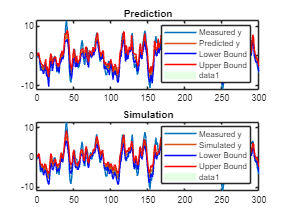

idcompare(arx_model_1, z, 3);  

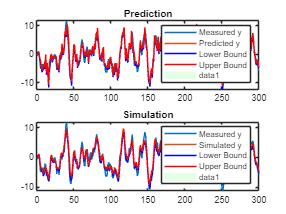

idcompare(oe_model_1, z, 3);

z1_half = z1(1:100, :);
z1_valid = z1(101:200, :);
z2_half = z2(1:100, :);
z2_valid = z2(101:200, :);

arx_model_z1 = arxfit(z1_half, [2, 2, 1]);
oe_model_z1 = oefit(z1_half, [2, 2, 1]);

arx_model_z1_tf = id2tf(arx_model_z1);
oe_model_z1_tf = id2tf(oe_model_z1);

ltiview('step', arx_model_z1_tf, oe_model_z1_tf);
ltiview('impulse', arx_model_z1_tf, oe_model_z1_tf);

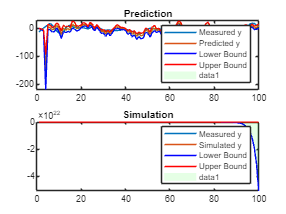

idcompare(arx_model_z1, z1_valid, 3);

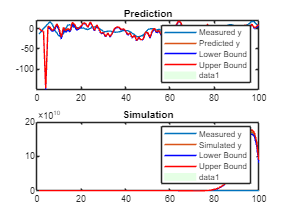

idcompare(oe_model_z1, z1_valid, 3);

arx_model_z2 = arxfit(z2_half, [2, 2, 1]);
oe_model_z2 = oefit(z2_half, [2, 2, 1]);

arx_model_z1_tf = id2tf(arx_model_z2);
oe_model_z1_tf = id2tf(oe_model_z2);

ltiview('step', arx_model_z1_tf, oe_model_z1_tf);
ltiview('impulse', arx_model_z1_tf, oe_model_z1_tf);

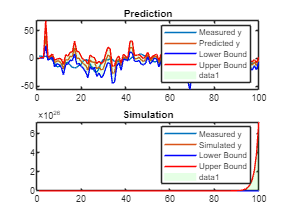

idcompare(arx_model_z2, z2_valid, 3);

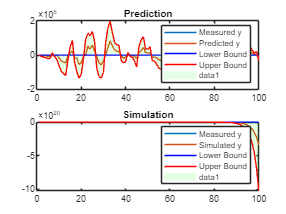

idcompare(oe_model_z2, z2_valid, 3);